In this demo, we set the flow velocity to be 5, which gives the dynamics of the pipe before flutter. More details about this demo can be found in [1]

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

clearvars
% close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

clear all;
nmodes = 4;
fcload = 1;
flowspeed = 5.2;
miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fext] = build_model(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[F, lambda] = functionFromTensors(M, C, K, fnl);
lambda = sort(lambda);

Create dynamical system 

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 eigenvalues are given as 
   1.0e+02 *

  -0.0106 + 0.1401i
  -0.0106 - 0.1401i
  -0.0645 + 0.5127i
  -0.0645 - 0.5127i
  -0.0879 + 0.0409i
  -0.0879 - 0.0409i
  -0.1177 + 1.1263i
  -0.1177 - 1.1263i



Choose Master subspace (perform resonance analysis)

We take the pair of unstable modes as the master subspace and compute the corresponding 2D unstable SSM

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 7;
resonant_modes = [1,2]; 
S.choose_E(resonant_modes);

(near) outer resonance detected for the following combination of master eigenvalues
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     1     1
     2     1
     2     2
     3     2
     3     3
     4     3
     4     4
     5     4
     5     5
     1     1
     1     2
     2     2
     2     3
     3     3
     3     4
     4     4
     4     5
     5     5
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0

[W0,R0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.10E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.40E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.08E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.66E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.74E-02 MB


%% Reduced dynamics in symbolic form
lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 0.06588\,{\rho_{1}}^{7}+0.1923\,{\rho_{1}}^{5}-0.882\,{\rho_{1}}^{3}-1.056\,\rho_{1}\\ -0.07309\,{\rho_{1}}^{6}+0.2606\,{\rho_{1}}^{4}+1.106\,{\rho_{1}}^{2}+14.01 \end{array}\right)$$

Convergence of backbone curve

syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

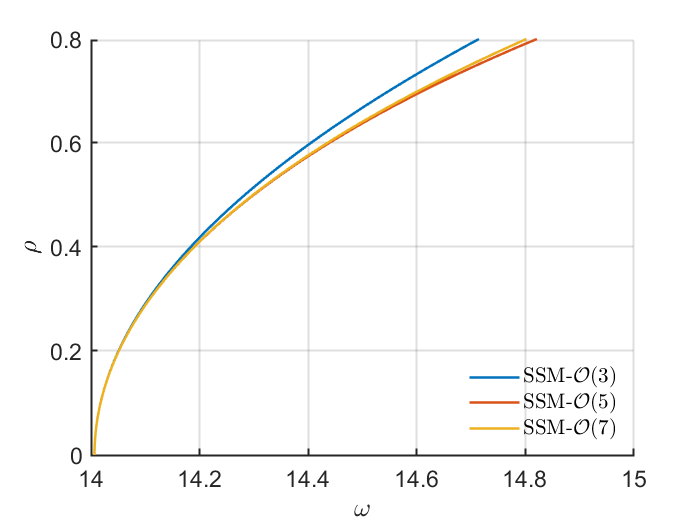

rhosamp = 0:0.01:0.8;
orders = [3 5 7];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

### Transient response prediction

We apply a static force at the free end and then release the beam to observe the free vibration of the pipe

phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
for k=1:n
   x    = 1;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   phiend(k) = phin;
end
loads = 1;
loadvector = loads.*phiend;
IC = getStaticResponse(K, M, F, loadvector);

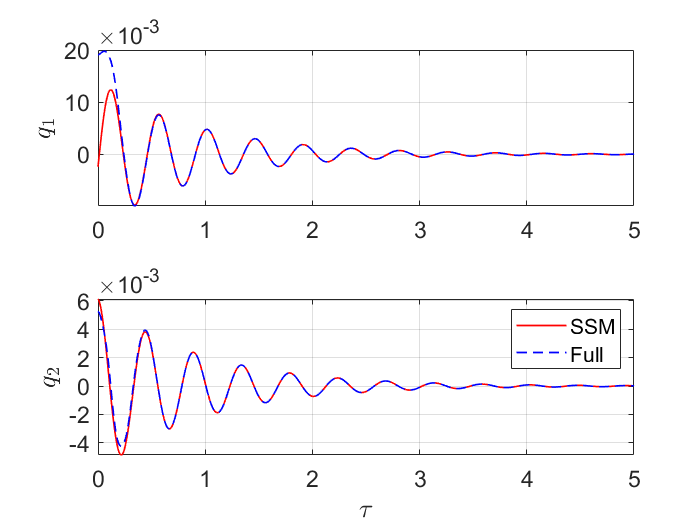

tf = 5;
nsteps = 1000;
outdof = [1 2 5];
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, IC);
[tInt,zInt] = time_integration_transient(DS,0,...
    'nSteps', nsteps, 'nCycles', ceil(tf/2/pi), ...
    'integrationMethod','ode45','outdof',outdof,'init',IC);

figure;
subplot(2,1,1)
plot(traj.time,traj.phy(:,1),'r-','LineWidth',1); hold on
plot(tInt,zInt(:,1),'b--','LineWidth',1);
ylabel('$q_1$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
xlim([0,min(traj.time(end),tInt(end))]);
subplot(2,1,2)
plot(traj.time,traj.phy(:,2),'r-','LineWidth',1); hold on
plot(tInt,zInt(:,2),'b--','LineWidth',1);
xlabel('$\tau$','Interpreter',"latex",'FontSize',14);
ylabel('$q_2$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
legend('SSM','Full')
xlim([0,min(traj.time(end),tInt(end))]);

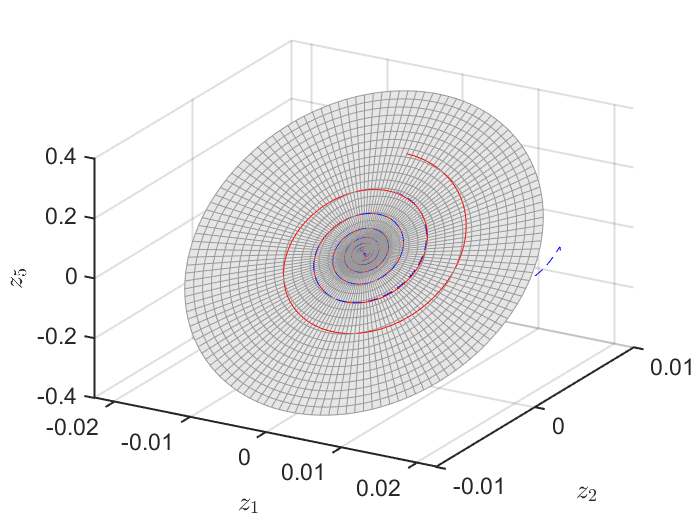


rhosamp = [0:0.01:0.2];
plotdofs = [1 2 3];
plot_2D_auto_SSM(W0,rhosamp,outdof(plotdofs));
view([30 30])
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-');
plot3(zInt(:,plotdofs(1)),zInt(:,plotdofs(2)),zInt(:,plotdofs(3)),'b--');

### Forced response - periodic orbit

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     1     1
     2     1
     2     2
     3     2
     3     3
     4     3
     4     4
     5     4
     5     5
     1     1
     1     2
     2     2
     2     3
     3     3
     3     4
     4     4
     4     5
     5     5
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645

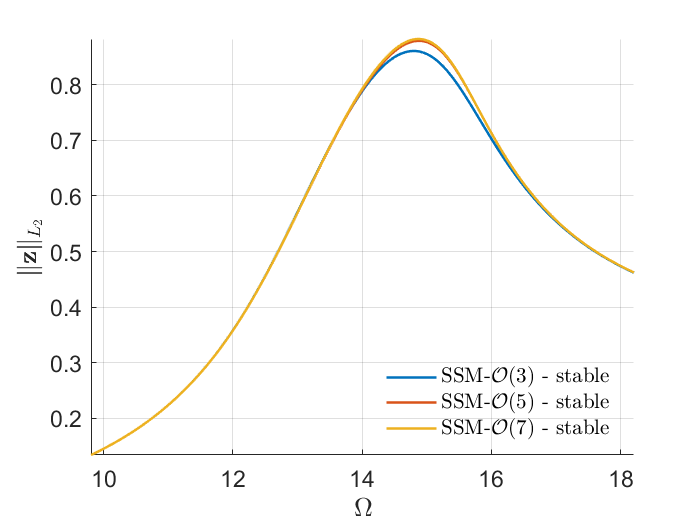

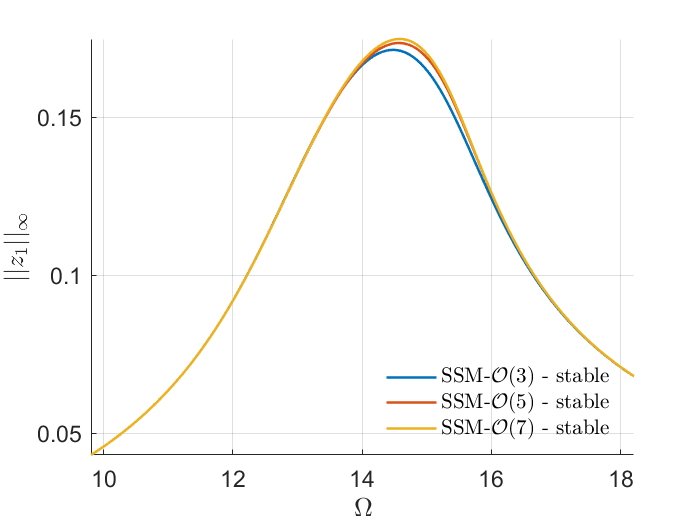

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     1     1
     2     1
     2     2
     3     2
     3     3
     4     3
     4     4
     5     4
     5     5
     1     1
     1     2
     2     2
     2     3
     3     3
     3     4
     4     4
     4     5
     5     5
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645

% add Forcing
kappas = [-1; 1];
coeffs = [fext fext]/2;
epsilon = 0.015;
DS.add_forcing(coeffs, kappas, epsilon);
set(DS.Options,'BaseExcitation',true);
% set up obervables
% disp at the free end
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);
% set up FRC options
freqrange = [0.7 1.3]*imag(D(1));
set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'fsolve');
set(S.contOptions, 'PtMX', 300, 'h_max', 0.1);
set(S.FRCOptions, 'omegaSampStyle', 'cocoBD');
set(S.FRCOptions, 'outdof',obs,'method','continuation ep','p0',[]);
S.extract_FRC('freq',freqrange,[3,5,7]);

figfrc = gcf;

(near) outer resonance detected for the following combination of master eigenvalues
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     1     1
     2     1
     2     2
     3     2
     3     3
     4     3
     4     4
     5     4
     5     5
     1     1
     1     2
     2     2
     2     3
     3     3
     3     4
     4     4
     4     5
     5     5
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 + 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0645 - 0.5127i
  -0.0

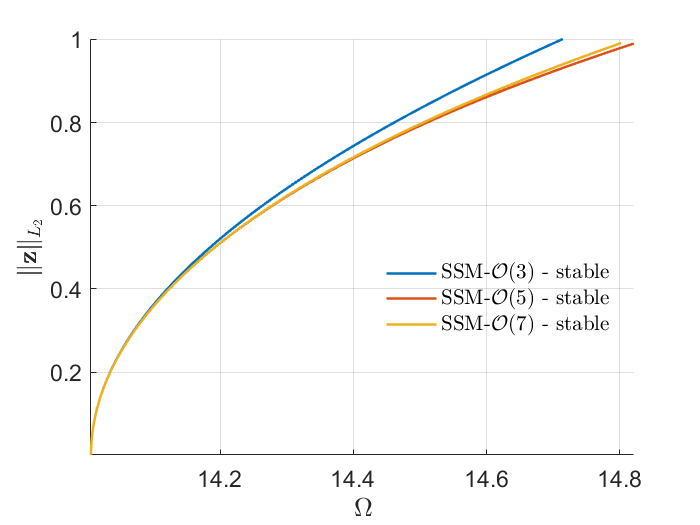

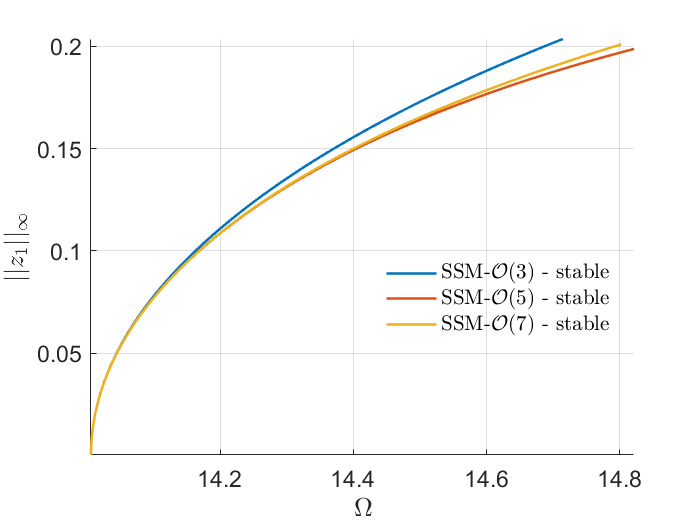

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.65E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.03E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.33E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.01E-02 MB
gamma = 
  -0.8820 + 1.1062i
   0.1923 + 0.2606i

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.10E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memo

% adding backbone curve
rhomax = 0.8;
BB = S.extract_backbone(resonant_modes, freqrange, 7,rhomax);

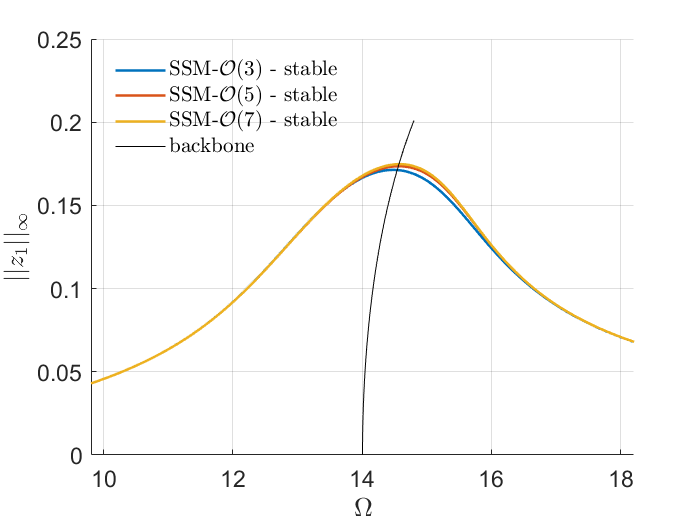

numPts = numel([BB.Omega]);
numOutdof = numel([BB.Aout])/numPts;
Aout = reshape([BB.Aout], [numOutdof, numPts]);
Aout = Aout';
figure(figfrc); hold on
plot([BB.Omega],Aout(:,1),'k-','DisplayName','backbone');
ylim([0,0.25]);

### validation using collocation method from COCO


 Run='bd_ld_v5.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.94e-01  1.39e+01    0.0    0.0    0.0
   1   1  2.57e-01  9.33e-01  1.44e-01  1.39e+01    0.0    0.0    0.0
   2   1  3.62e-01  6.93e-01  9.19e-02  1.39e+01    0.0    0.1    0.0
   3   1  6.02e-01  4.41e-01  3.65e-02  1.39e+01    0.0    0.1    0.0
   4   1  1.00e+00  1.75e-01  9.39e-05  1.39e+01    0.0    0.2    0.0
   5   1  1.00e+00  4.10e-04  4.65e-10  1.39e+01    0.0    0.2    0.0
   6   1  1.00e+00  1.54e-09  2.79e-16  1.39e+01    0.0    0.2    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:00   1.3927e+01      1  EP      9.8045e+00   6.4085e-01   1.5000e-02   4.3032e-02
   10  00:00:06   1.7455e+01      2          1.2170e+01   5.1630e-01   1.5000e-02   9.7660e-02
   20  00:00:10  

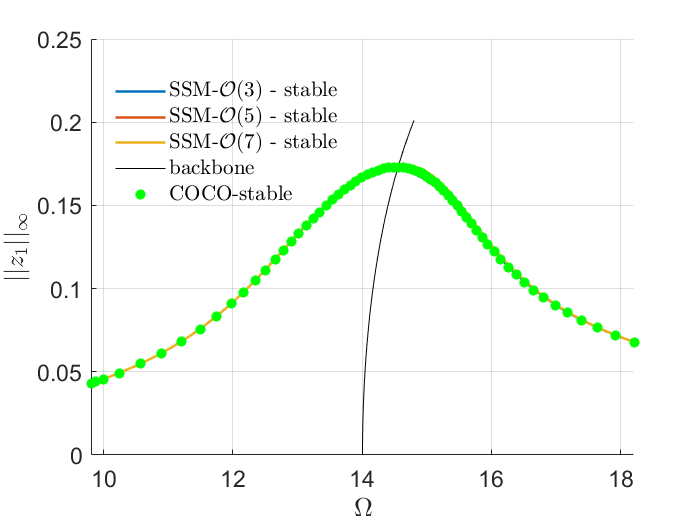

nCycles = 500;
coco = cocoWrapper(DS, nCycles, obs);
set(coco.Options, 'PtMX', 1000, 'NTST',10, 'dir_name', 'bd_ld_v5');
set(coco.Options, 'NAdapt', 1);
coco.initialGuess = 'linear';
start = tic;
bd_ld = coco.extract_FRC(freqrange);

timings.cocoFRCbd_ld = toc(start)

timings = struct with fields:
    cocoFRCbd_ld: 32.7270
